p = [[0; 0] [0; 1] [1; 0] [1; 1]]

p =      0     0     1     1
     0     1     0     1


t = [0 1 1 0]

t =      0     1     1     0



net = newff(p, t, [2], {'tansig' 'logsig'}, 'traingd','', 'mse', {}, {}, '')


net =

    Neural Network
 
              name: 'Custom Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 9
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      <a href="matlab:doc nnproperty.net_inputConnect">inputConnect</a

Training:

net = init(net)


net =

    Neural Network
 
              name: 'Custom Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 9
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      <a href="matlab:doc nnproperty.net_inputConnect">inputConnect</a

[trained_net, stats] = train(net, p, t);

Plot:

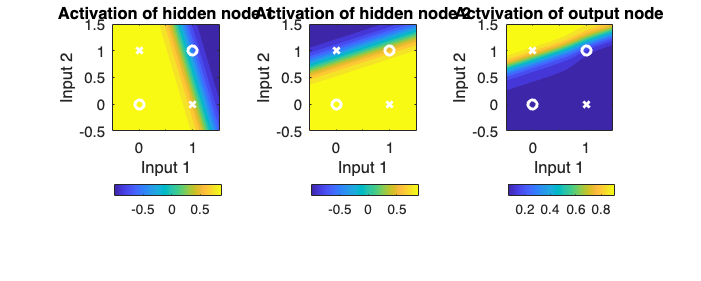

plot_xor(trained_net)

Simulate:

sim(trained_net, [0; 0]) % Returns one output.

ans = 0.1081

sim(trained_net, p) % Returns a vector of outputs.

ans =     0.1081    0.8550    0.0974    0.1776


Now try for multiple epochs

Training with learning rate = 0.01, Epochs = 5000


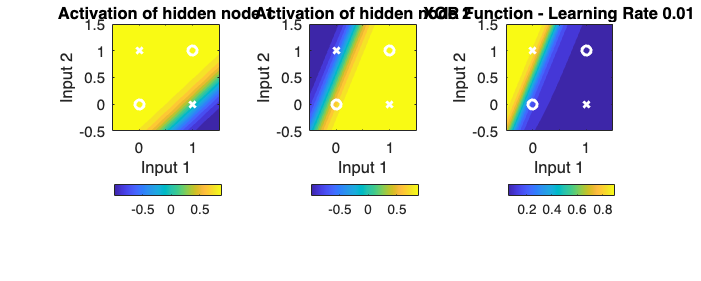

Training with learning rate = 0.10, Epochs = 3000


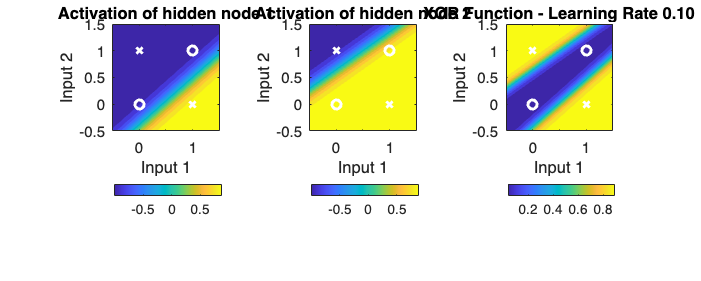

Training with learning rate = 0.50, Epochs = 2000


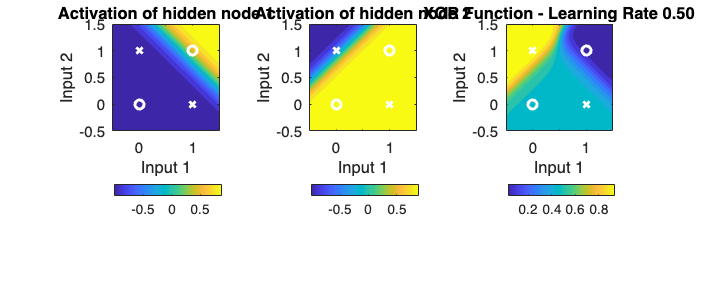

Training with learning rate = 1.00, Epochs = 1500


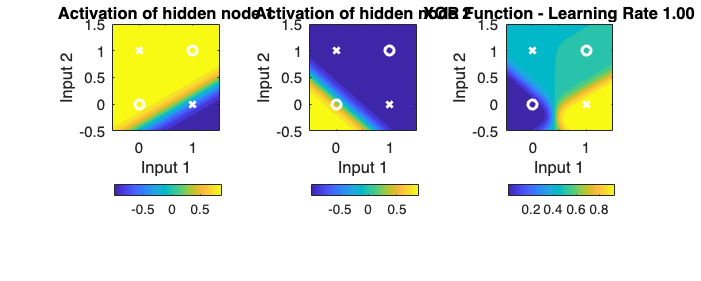

Training with learning rate = 5.00, Epochs = 1000


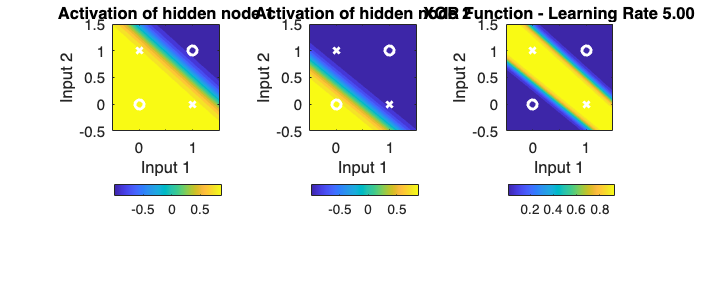

Training with learning rate = 10.00, Epochs = 800


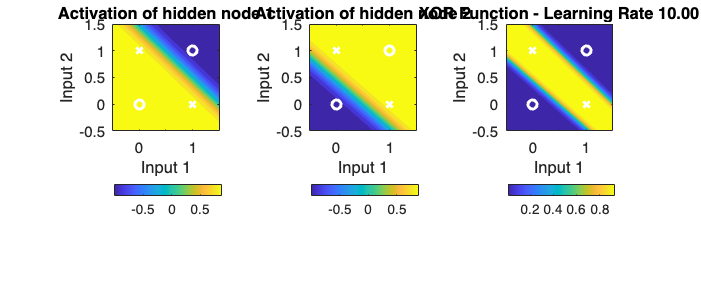

Training with learning rate = 20.00, Epochs = 500


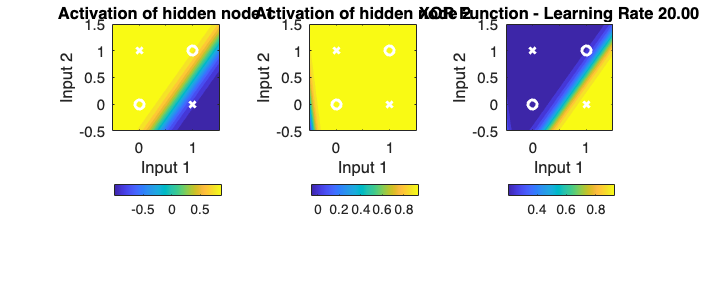

learning_rates = [0.01, 0.1, 0.5, 1, 5, 10, 20]; % Different learning rates

epochs_list = [5000, 3000, 2000, 1500, 1000, 800, 500]; % Adjusted epochs

for i = 1:length(learning_rates)
    % Create and initialize the network
    net = newff(p, t, [2], {'tansig', 'logsig'}, 'traingd', '', 'mse', {}, {}, '');
    net.trainParam.lr = learning_rates(i); % Set learning rate
    net.trainParam.epochs = epochs_list(i); % Set epochs
    net.trainParam.min_grad = 0; % Ensure training does not stop early

    % Train the network
    net = init(net);
    [trained_net, stats] = train(net, p, t);
    
    % Display results
    fprintf('Training with learning rate = %.2f, Epochs = %d\n', learning_rates(i), epochs_list(i));
    
    % Check if the network learned XOR function
    figure;
    plot_xor(trained_net);
    title(sprintf('XOR Function - Learning Rate %.2f', learning_rates(i)));
end



Test out above:

sim(trained_net, [0; 0])  % Predict for input [0,0]
sim(trained_net, [0; 1])  % Predict for input [0,1]
sim(trained_net, [1; 0])  % Predict for input [1,0]
sim(trained_net, [1; 1])  % Predict for input [1,1]

plot


figure % Create a new figure.
ax = axes % Get a handle to the figure's axes.
hold on % Set the figure to not overwrite old plots.
grid on % Turn on the grid.

plot(ax, stats.perf)
